## Survival ratio computation by bistable using LHS

### LHS for parameters

clear;clc;
% load parameters
par_init = importdata('par_base_IAV_clock_values.txt');
par_init = par_init.data;

ratio = 0.05;
N = 100;  % parameter set number

par_bound = zeros(2, length(par_init));
par_bound(1, :) = par_init .* (1 - ratio);
par_bound(2, :) = par_init .* (1 + ratio);

lhs_rad = lhsdesign(N, length(par_bound));
par_lhs = par_bound(1, :) + lhs_rad .* (par_bound(2, :) - par_bound(1, :));

% write lhs parameters to file
file_par = fopen('lhs_par.txt', 'w');
for i = 1:N
    fprintf(file_par, '%.10f ', par_lhs(i, :));
    fprintf(file_par, '\n');
end
fclose(file_par);

### Run ODEs

% load immune parameter set
par_lhs = importdata('lhs_par.txt');

% load clock parameters
par_clock = load('par_clock.csv');

% load inflammation parameters
par_infla = importdata('par_infla.txt');
par_infla = par_infla.data;

par_num = 100;
var_num = 27;

y0 = zeros(27, 1);
y0_IAV = importdata('init_base.txt');
y0_IAV = y0_IAV.data;
for i = 13:26
    y0(i) = y0_IAV(i - 12);
end

tmax = 2000;
tspan = 0:1:tmax;

% run odes for ZT11
y11s = zeros(length(tspan), var_num, par_num);
t_IAV_11 = 511;
parfor i = 1:par_num
    [~, y11s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_11, par_infla);
end

% run odes for ZT23
y23s = zeros(length(tspan), var_num, par_num);
t_IAV_23 = 499;
parfor i = 1:par_num
    [~, y23s(:, :, i)] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_23, par_infla);
end

% run odes for ZT11 with clock knock out
y11_ko = zeros(length(tspan), var_num, par_num);
t_IAV_11 = 511;
parfor i = 1:par_num
    [~, y11_ko(:, :, i)] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_11, par_infla);
end

% run odes for ZT23 with clock knock out
y23_ko = zeros(length(tspan), var_num, par_num);
t_IAV_23 = 499;
parfor i = 1:par_num
    [~, y23_ko(:, :, i)] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_lhs(i, :), t_IAV_23, par_infla);
end

### Plot figuires

plot time evolution

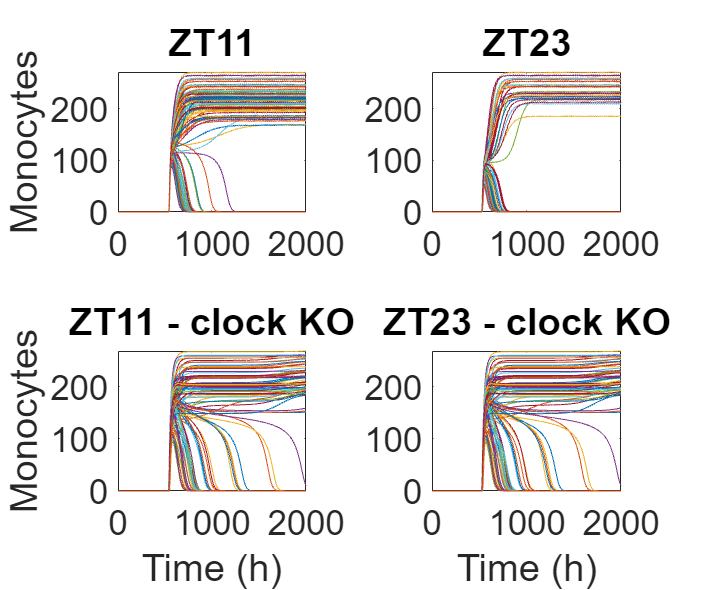

figure;
xSize = 20; X=xSize; ySize = 15;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(2, 2, 1); hold on; set(gca,'Fontsize',26); box on;
for i = 1:par_num
    plot(tspan, y11s(:, 18, i));
end
ylabel('Monocytes');
title('ZT11');
hold off;

subplot(2, 2, 2); hold on; set(gca,'Fontsize',26); box on;
for i = 1:par_num
    plot(tspan, y23s(:, 18, i));
end
title('ZT23');
hold off;

subplot(2, 2, 3); hold on; set(gca,'Fontsize',26); box on;
for i = 1:par_num
    plot(tspan, y11_ko(:, 18, i));
end
xlabel('Time (h)'); ylabel('Monocytes');
title('ZT11 - clock KO');
hold off;

subplot(2, 2, 4); hold on; set(gca,'Fontsize',26); box on;
for i = 1:par_num
    plot(tspan, y23_ko(:, 18, i));
end
xlabel('Time (h)');
title('ZT23 - clock KO');
hold off;

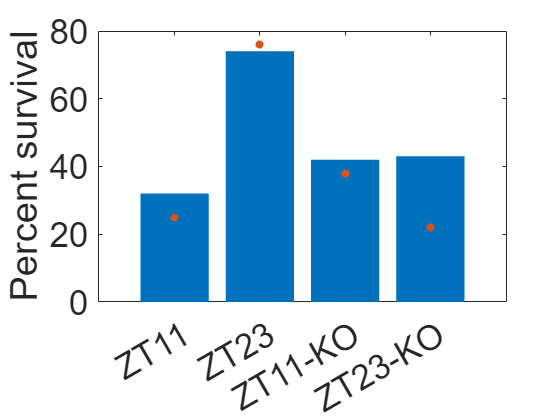


% plot survival ratios
survival_num_11 = 0;
survival_num_23 = 0;
survival_num_11_ko = 0;
survival_num_23_ko = 0;
for i = 1:par_num
    if y11s(end, 18, i) < 10
        survival_num_11 = survival_num_11 + 1;
    end
    if y23s(end, 18, i) < 10
        survival_num_23 = survival_num_23 + 1;
    end
    if y11_ko(end, 18, i) < 10
        survival_num_11_ko = survival_num_11_ko + 1;
    end
    if y23_ko(end, 18, i) < 10
        survival_num_23_ko = survival_num_23_ko + 1;
    end
end
survival_ratio_11 = survival_num_11 / par_num * 100;
survival_ratio_23 = survival_num_23 / par_num * 100;
survival_ratio_11_ko = survival_num_11_ko / par_num * 100;
survival_ratio_23_ko = survival_num_23_ko / par_num * 100;
figure;
set(gca,'Fontsize',26); box on; hold on;
bar_name = categorical({'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
bar_name = reordercats(bar_name, {'ZT11', 'ZT23', 'ZT11-KO', 'ZT23-KO'});
bar_data = [survival_ratio_11, survival_ratio_23, survival_ratio_11_ko, survival_ratio_23_ko];
bar(bar_name, bar_data, 'FaceColor', '#0072BD', 'EdgeColor', 'none');

survival_data = [25, 76, 38, 22];
scatter(bar_name, survival_data, 'filled');
ylabel('Percent survival');
hold off;